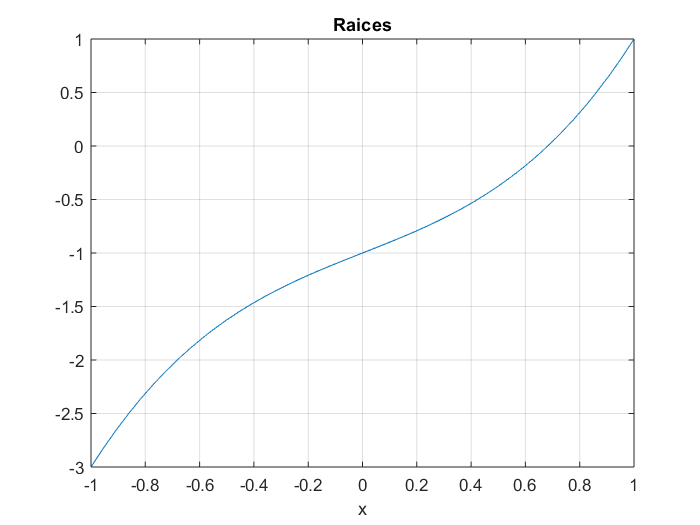

f = @(x) x.^3 + x - 1; %@ es función anonima
a = -1;
b = 1;
fplot(f,[a,b]);
xlabel('x');
title('Raices');
grid on;


[x,i] = biseccion(f,0.6,0.8)

x =    0.682327803828019


i =     49


[x,i] = falsaPosicion(f,0.6,0.8)

x =    0.682327803828019


i =     15


[x,i] = newtonRaphson(f,0.6,0.8)

$$fsym = x^{3}+x-1$$

$$dfs = 3\,x^{2}+1$$

df = function_handle with value:
    @(x)x.^2.*3.0+1.0


x =    0.682327803828019


i =      5


# Problema: Encontrar raíz

## Tanque esferico

Se diseña un tanque esferico, el volumen del liquido puede computarse como : $V=\pi \times h^2 \times \frac{\left\lbrack 3R-h\right\rbrack }{3}$ donde v = volumen, h = profundidad del agua, R = radio del tanque.

Si R = 3, que h se necesita para que V=30;

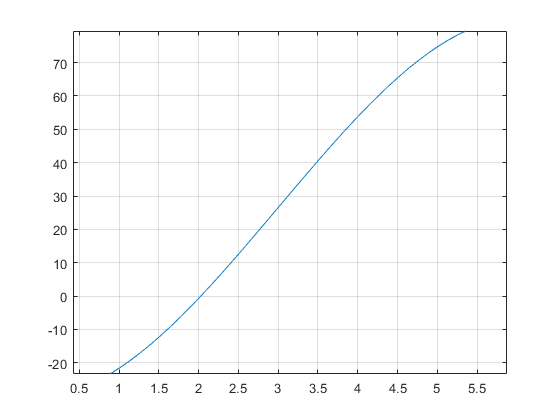

v = @(h) (pi.*(h.^2)).*((3.*r)-h)/3 -vd;
r = 3;
a = 0;
b = 2*r;
fplot(v,[a,b]);
grid on;

vd =30;
disp("Falsa Posición")

Falsa Posición


[x,i] = falsaPosicion(v,a,b)

x =    2.026905728310013


i =      9


disp("Newton Raphson")

Newton Raphson


% por la gráfica podemos ver que la raíz está
%entre 1 y 3 por lo que a =1 y b =30
[x,i] = newtonRaphson(v,1,3)

$$fsym = -\frac{\pi \,h^{2}\,\left(h-9\right)}{3}-30$$

$$dfs = -\frac{\pi \,h^{2}}{3}-\frac{2\,\pi \,h\,\left(h-9\right)}{3}$$

df = function_handle with value:
    @(h)h.^2.*pi.*(-1.0./3.0)-h.*pi.*(h-9.0).*(2.0./3.0)


x =    2.026905728310013


i =      4


disp("Bisección")

Bisección


[x,i] = biseccion(v,a,b)

x =    2.026905728310013


i =     53


# Examen pasado

## Problema 3:

El método de Newton-Raphson permite encontrar la raíz x de una función de tal manera que f(x)=0. Para encontrar un valor óptimo de f(x) puede usarse una función similar recordando que en un punto crítico f’(x)=0. Programa la función [x,i,min] = optNR(f, x0) que encuentra un punto crítico de f iniciando con el valor x0. El valor lógico min regresado debe indicar si el valor crítico se trata de un mínimo (true) o un máximo (false). Prueba tu función con : $f\left(x\right)=2\times \mathrm{Sin}\left(x\right)-\frac{x^2 }{10}$

- Grafica f(x) en el intervalo [0,4] para encontrar un valor adecuado para x0.

- Utiliza tu función de optimización que implementa la proporción aurea para verificar que obtienes el mismo valor.

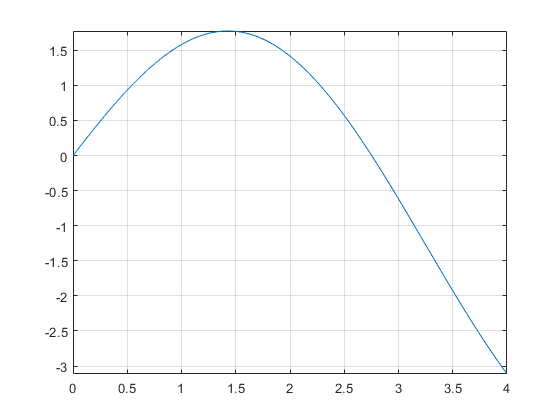

fx = @(x) 2*sin(x) - x.^2/10;
fplot(fx,[0,4])
grid on;

[x,i,min] = newtownRaphsonOptimizacion(fx,0,2)

$$fsym = 2\,\sin\left(x\right)-\frac{x^{2}}{10}$$

$$dfs = 2\,\cos\left(x\right)-\frac{x}{5}$$

df = function_handle with value:
    @(x)x.*(-1.0./5.0)+cos(x).*2.0


$$dfs2 = -2\,\sin\left(x\right)-\frac{1}{5}$$

df2 = function_handle with value:
    @(x)sin(x).*-2.0-1.0./5.0


x =    1.427551778764594


i =      5


min = logical
   0
